Valence signature performance on Study 1

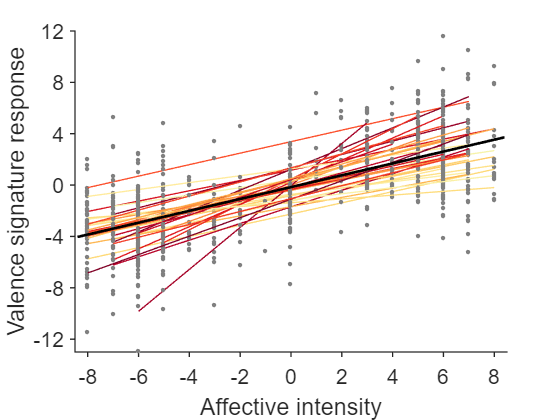

datadir = 'G:\A_arousal_analysis\data';
resultsdir = 'G:\A_arousal_analysis\results';
load(fullfile(resultsdir, 'A_valence_signature_pred_Study1.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
% pre-define colormap
uID = unique(subject);
nsub = length(uID);
subj_plot = subject;
valence_within_corrs = zeros(nsub, 1);
for i = 1:nsub
subj_idx = subj_plot==uID(i);
valence_within_corrs(i,1) = corr(valence(subj_idx), valence_prediction(subj_idx));
end


n_colors = 76;
n_corrs = length(valence_within_corrs);
[~, corr_idx] = sort(valence_within_corrs);
idx_float = linspace(1, n_colors, n_corrs);
idx = round(idx_float);
corr_colors = col_diff_map2(idx+75, :);
cols(corr_idx, :) = corr_colors;


subj_plot = subject;
uID = unique(subj_plot);

figure;
hold on

for i = 1:nsub
    subj_idx = subj_plot==uID(i);
    plot(valence(subj_idx), valence_prediction(subj_idx), '.', 'color', [.5 .5 .5], 'MarkerSize', 10)
    bls = regress(valence_prediction(subj_idx), [ones(sum(subj_idx),1), valence(subj_idx)]);
    plot(valence(subj_idx), bls(1)+bls(2)*valence(subj_idx), 'Color', cols(i,:),'linewidth', 1);
end
bls = regress(valence_prediction, [ones(length(valence),1), valence]);
plot([-8.4; valence; 8.4], bls(1)+bls(2)*[-8.4; valence; 8.4], 'Color', 'k', 'linewidth', 2);

set(gca,'YLim', [-13 12], 'ytick',-12:4:12, 'XLim', [-8.5 8.5], 'xtick',-8:2:8, 'tickdir', 'out');
xlabel('Affective intensity')
ylabel('Valence signature response');
set(gca,'FontName','Helvetica','FontSize',16, 'LineWidth', 1)

% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 6.5 5.5]);
% print('-dtiff', 'A_valence_signature_study1', '-r400')
% close all

Valence signature performance on Study 2

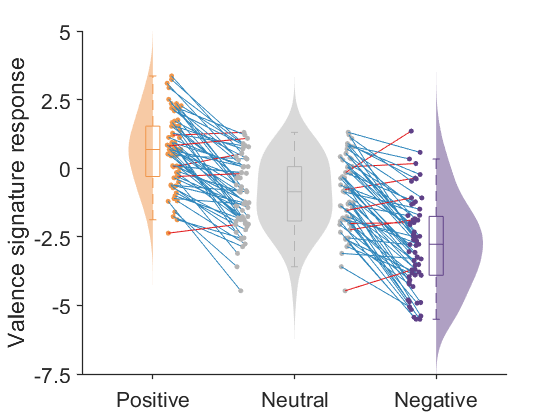

clear, clc
close all
% pred Study 2
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_valence_pattern.mat'))
load(fullfile(datadir, 'A_arousal_validation_connectivity_latest.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;
negative_PE =  negative_FC * weight';
positive_PE = positive_FC * weight';
neutral_PE = neutral_FC * weight';

dataConditions = {positive_PE, neutral_PE, negative_PE};
conditionLabels = {'Positive', 'Neutral', 'Negative'};

lefthigher = dataConditions{1} > dataConditions{2};
linecolors{1} = zeros(length(lefthigher), 3);
linecolors{1}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
linecolors{1}(~lefthigher, :) = repmat([0.8902    0.1020    0.1098], sum(~lefthigher), 1);

lefthigher = dataConditions{2} > dataConditions{3};
linecolors{2} = zeros(length(lefthigher), 3);
linecolors{2}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
linecolors{2}(~lefthigher, :) = repmat([0.8902    0.1020    0.1098], sum(~lefthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.03, 'connectwidth', 0.5, 'colors', cols(1:3,:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('Valence signature response');
set(gca,'YLim', [-7.5 5], 'ytick',-7.5:2.5:5, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',16, 'LineWidth', 1)


%axis square
set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 6.5 5.5]);
% print('-dtiff', 'A_valence_signature_study2.tif', '-r400')
% close all